%% ----- Initialisation of the environment ----- %%

% Path Construction %
init_paths();

All necessary paths have been added.



% Default Simulation Arguments %

args = SimArgParse_Reentrant();

% Adjusting Simulation Parameters %
args.mesh = 'ventricles_coarser_LV_infarct';
args.input_state = '2_LV_top_3550.roe';
args.scar_flag = 1;
args.scar_region = 300;
args.isthmus_region = 400;
args.conmul = 0.25;
%args.ATP_coupling = 0.88;
%args.ATP_CL = 0.88;
args.ATP_strength = 900; 

% Default ICD Parameter Arguments %

argsICD = initialise_ICD();

% Results Folders %
todayDate = datetime('yesterday', 'Format', 'yyyy-MM-dd')

todayDate = datetime
   2025-07-03


newFolderName = sprintf('2025-07-03_Patient_Reentrant_1');
newFolderPath = fullfile('OUTPUT', newFolderName);

% Save the passed parameters to the output folder for later inspection %
saveprintparams_reentrant(args, argsICD, newFolderPath);

Simulation parameters saved to text log: OUTPUT/2025-07-03_Patient_Reentrant_1/SimParams.txt



% Pause to allow environment and file path set up %
pause(2)

2025-07-03
Moving 28 files to OUTPUT/2025-07-03_Patient_Reentrant_1...
Moving 5 simulation folders to OUTPUT/2025-07-03_Patient_Reentrant_1...
Moved 2025-07-03_ATP_APP_INPUT_checkpoint.17000.0.roe_272.77_atpbcl_17333.16_atpstart_10.00_atpdec_8.00_atppls to OUTPUT/2025-07-03_Patient_Reentrant_1/Sim_folders/2025-07-03_ATP_APP_INPUT_checkpoint.17000.0.roe_272.77_atpbcl_17333.16_atpstart_10.00_atpdec_8.00_atppls


Moved 2025-07-03_ATP_APP_INPUT_checkpoint.9000.0.roe_269.93_atpbcl_9623.93_atpstart_8.00_atppls to OUTPUT/2025-07-03_Patient_Reentrant_1/Sim_folders/2025-07-03_ATP_APP_INPUT_checkpoint.9000.0.roe_269.93_atpbcl_9623.93_atpstart_8.00_atppls


Moved 2025-07-03_ventricles_coarser_LV_infarct_INPUT_2_LV_top_3550.roe_conmul_0.25 to OUTPUT/2025-07-03_Patient_Reentrant_1/Sim_folders/2025-07-03_ventricles_coarser_LV_infarct_INPUT_2_LV_top_3550.roe_conmul_0.25


Moved 2025-07-03_ventricles_coarser_LV_infarct_INPUT_state.ATP_end_12783.39.roe_conmul_0.25 to OUTPUT/2025-07-03_Patient_Reentrant_1/Sim_folders/2025-07-03_ventricles_coarser_LV_infarct_INPUT_state.ATP_end_12783.39.roe_conmul_0.25


Moved 2025-07-03_ventricles_coarser_LV_infarct_INPUT_state.ATP_end_20515.3.roe_conmul_0.25 to OUTPUT/2025-07-03_Patient_Reentrant_1/Sim_folders/2025-07-03_ventricles_coarser_LV_infarct_INPUT_state.ATP_end_20515.3.roe_conmul_0.25
Deleting 25 files and 0 PETSc folders...


Episode results saved to: OUTPUT/2025-07-03_Patient_Reentrant_1


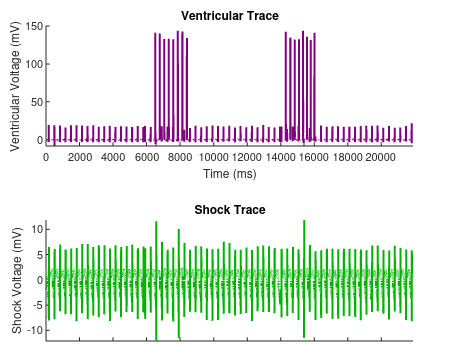

Plot saved as OUTPUT/2025-07-03_Patient_Reentrant_1/Full_Episode_Trace.png


% Testing the file clean up 
% disp(args.EGM_name);
% disp(args.EGM_features_name);
output_clean(newFolderPath, args.EGM_name, args.EGM_features_name, 'Reentrant_VT', todayDate)